# 基于SVM的回归预测分析——上证开盘指数预测

- 上证指数：开盘指数，指数最高值，指数最低值，收盘指数，当日交易量，当日交易额

- 数据来源：[http://quotes.money.163.com/trade/lsjysj_zhishu_000001.html](http://quotes.money.163.com/trade/lsjysj_zhishu_000001.html)

## libsvm 下载和安装：

- libsvm 下载链接：[https://www.csie.ntu.edu.tw/~cjlin/libsvm/#download](https://www.csie.ntu.edu.tw/~cjlin/libsvm/#download)

- libsvm 使用：解压之后放到常用目录，然后设置路径，选择 matlab 文件夹运行 make.m 文件，编译成功即可使用

- 参数说明

## 代码部分：

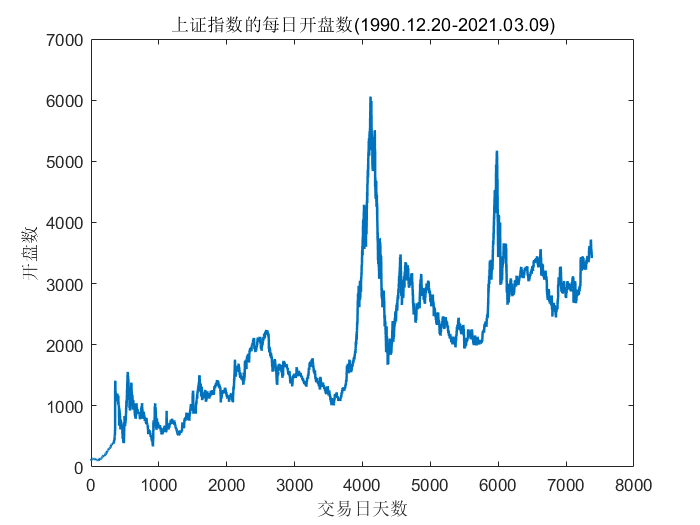

clear;clc;close all;
%%%%%%%%%%%%%%%%%%%%%%%%%% 读取数据 
file = readtable('000001.xlsx', 'VariableNamingRule', 'preserve');
data = file(:, 2:end);
data = table2array(data);
% 数据清洗
[row, col] = find(isnan(data));
data(row, :) = [];
% 根据前一天的上证指数预测下一天的开盘指数
output = data(2:end, 1);
input = data(1:end-1, :);
% 绘图
figure;
plot(output, 'LineWidth', 1.5);
title('上证指数的每日开盘数(1990.12.20-2021.03.09)');
xlabel('交易日天数');
ylabel('开盘数');

% 数据分成训练集和测试集
train_number = 7000;
train_input = input(1:train_number, :);
train_output = output(1:train_number, :);
test_input = input(train_number+1 : end, :);
test_output = output(train_number+1 : end, :);
% 数据预处理,将原始数据进行归一化
[Ttrain_output, PStrain_output] = mapminmax(train_output');	
Ttrain_output = Ttrain_output';
[Ttrain_input, PStrain_input] = mapminmax(train_input');	
Ttrain_input = Ttrain_input';
%%%%%%%%%%%%%%%%%%%%%%%%%% 交叉校验，获取最佳的 c 和 g 参数
best_c = 0;
best_g = 0;
best_mse = Inf;
log2c = -4 : 0.5 : 4;
log2g = -4 : 0.5 : 4;
cg = nan(length(log2c), length(log2g));
for i = 1:length(log2c)
    for j = 1:length(log2g)
        c = 2^log2c(i);
        g = 2^log2g(j);
        % -v 交叉验证参数，在训练的时候需要
        cmd = sprintf('-v 3 -c %f -g %f -s 3 -t 2 -p 0.1 -h 0', c, g);
        cg(i, j) = svmtrain(Ttrain_output, Ttrain_input, cmd);
        % 找最小值
        if cg(i, j) < best_mse
            best_mse = cg(i, j);
            best_c = c;
            best_g = g;
        end
    end
end

*
optimization finished, #iter = 31
nu = 0.011626
obj = -1.240464, rho = 0.030537
nSV = 57, nBSV = 54
*
optimization finished, #iter = 41
nu = 0.011113
obj = -1.237565, rho = 0.042929
nSV = 55, nBSV = 50
*
optimization finished, #iter = 32
nu = 0.011355
obj = -1.226325, rho = 0.044602
nSV = 54, nBSV = 51
Cross Validation Mean squared error = 0.0011194
Cross Validation Squared correlation coefficient = 0.992484
*
optimization finished, #iter = 33
nu = 0.011472
obj = -1.049670, rho = 0.026018
nSV = 54, nBSV = 51
*
optimization finished, #iter = 32
nu = 0.010375
obj = -1.045892, rho = 0.022312
nSV = 51, nBSV = 47
*
optimization finished, #iter = 28
nu = 0.010310
obj = -1.033478, rho = 0.025258
nSV = 50, nBSV = 47
Cross Validation Mean squared error = 0.00174941
Cross Validation Squared correlation coefficient = 0.988899
*
optimization finished, #iter = 51
nu = 0.012275
obj = -0.942672, rho = 0.015079
nSV = 61, nBSV = 56
*
optimization finished, #iter = 41
nu = 0.011250
obj = -0.937006, rh

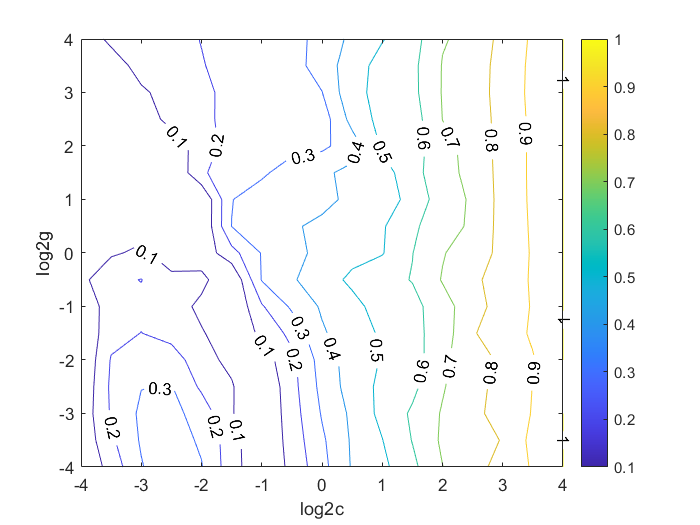

% 绘图
figure;
[cg, ~] = mapminmax(cg, 0, 1);
contour(log2c, log2g, cg, 'ShowText', 'on');
colorbar
xlabel('log2c');
ylabel('log2g');
zlabel('cg');

% 利用最佳参数进行 SVM 网络训练
cmd = sprintf('-c %f -g %f -s 3 -t 2 -p 0.01', best_c, best_g);
model = svmtrain(Ttrain_output, Ttrain_input, cmd);

.
*
optimization finished, #iter = 1984
nu = 0.062565
obj = -5.249989, rho = -0.081368
nSV = 462, nBSV = 418


% SVM 网络训练效果
[train_predict, ~, ~] = svmpredict(Ttrain_output, Ttrain_input, model);

Mean squared error = 5.1496e-05 (regression)
Squared correlation coefficient = 0.999606 (regression)


% 反归一化
train_predict = mapminmax('reverse', train_predict', PStrain_output);
train_predict = train_predict';
% 绘图
figure("Position", [50, 50, 800, 700]);
subplot(2, 2, 1);
plot(train_output, '.');
hold on
plot(train_predict);
hold off;
legend('训练数据', '训练结果');
title('SVM 网络训练效果');
xlabel('交易日序号');
ylabel('开盘数');
% 加一个箭头
% annotation('textarrow', [0.3, 0.2], [0.38, 0.31]);
% 局部放大
% part_data1 = train_output(500:600);
% part_data2 = train_predict(500:600);
% axes('position', [0.15 0.4 0.3 0.4]);  
% plot(part_data1, '.');
% hold on
% plot(part_data2);
% hold off;
% title('开盘数（500-600）');
% set(gca, "XTick", [], 'YTick', []);
subplot(2, 2, 2);
train_error = (train_predict - train_output) ./ train_output;
plot(train_error, 'r');
hold on
plot(0.05*ones(size(train_error)), 'b');
plot(-0.05*ones(size(train_error)), 'b');
hold off
title('误差图');
xlabel('交易日序号');
ylabel('误差相对值');
% 测试集
% 归一化
Ttest_input = mapminmax('apply', test_input', PStrain_input);
Ttest_input = Ttest_input';
% SVM 网络测试效果
[test_predict, ~, ~] = svmpredict(test_output, Ttest_input, model);

Mean squared error = 9.85614e+06 (regression)
Squared correlation coefficient = 0.992462 (regression)


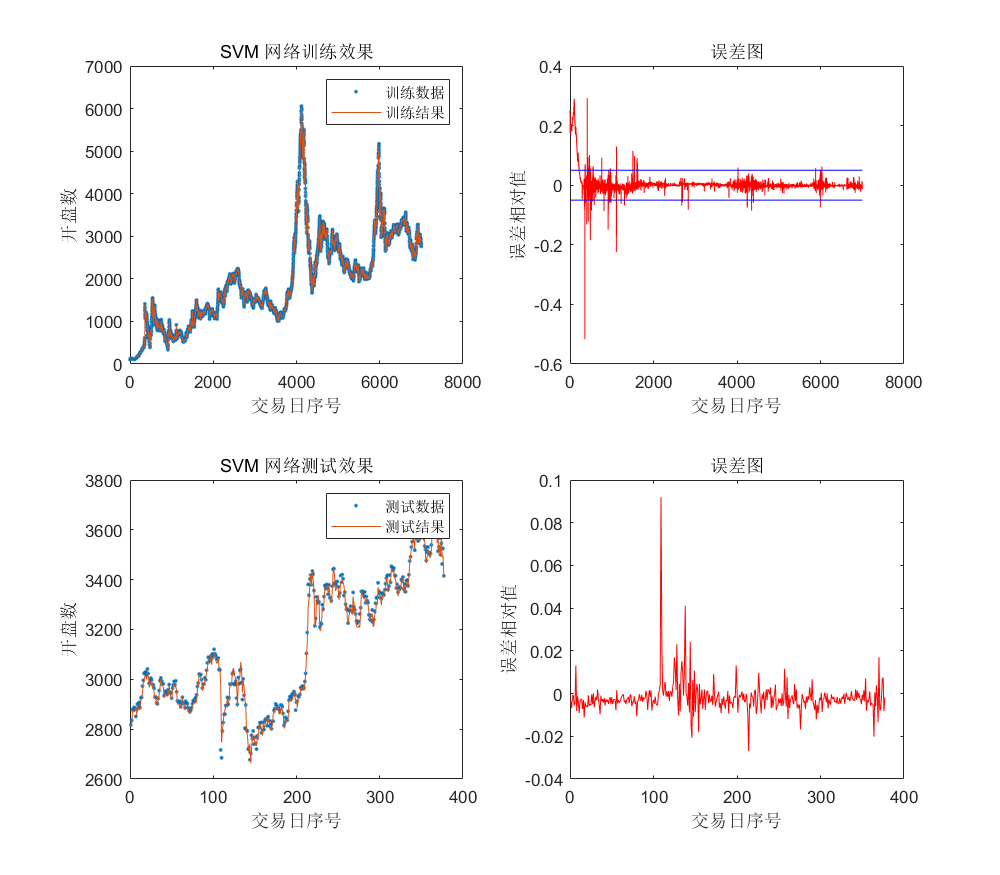

% 反归一化
test_predict = mapminmax('reverse', test_predict', PStrain_output);
test_predict = test_predict';
% 绘图
subplot(2, 2, 3);
plot(test_output, '.');
hold on
plot(test_predict);
hold off;
legend('测试数据', '测试结果');
title('SVM 网络测试效果');
xlabel('交易日序号');
ylabel('开盘数');
subplot(2, 2, 4);
test_error = (test_predict - test_output) ./ test_output;
plot(test_error, 'r');
title('误差图');
xlabel('交易日序号');
ylabel('误差相对值');